# Lab work C

clear all
close all
lab_work_C_init_routine;

## Case 1: you are allowed to make use of the measurement in h1 and h2

lab_work_C_preparing_the_model

pm1_mf = function_handle with value:
    @(u_bar)u_bar.*3.277899884284337e-1-u_bar.^2.*9.88758313621772e-3+u_bar.^3.*1.567756031883916e-4-2.914041336753123


% *** Checking the order of the system ***

% Order 0? No.
% Order 1? No.
dh = jacobian(h,x)*dx;
% Order 2? Yes.
ddh = jacobian(dh,x)*dx;

% Function to obtain the state xi from x, so xi = T(x)
T = [h;dh];
T_mf = matlabFunction(T)

T_mf = function_handle with value:
    @(x1,x2)[x2.*7.456422751238219e-1-1.648066384406454;sqrt(x1.*1.962e+3+6.2784e+3).*3.841187477910597e-3-sqrt(x2.*1.962e+3+6.2784e+3).*3.841187477910597e-3]


% The reasoning is this...
% u_bar = k(xi,r)
syms r;

pole1 = -0.05;
pole2 = -0.075;
L = conv([1 -pole1],[1 -pole2]);
L = flip(L(2:end));

Lr = L(1);

k = solve(ddh==(-L*T+Lr*r),u_bar);
k_mf = matlabFunction(k)

k_mf = function_handle with value:
    @(r,x1,x2)sqrt(x1.*1.962e+3+6.2784e+3).*(r.*(3.0./8.0e+2)-x2.*2.796158531714332e-3+1.0./sqrt(x2.*1.962e+3+6.2784e+3).*(sqrt(x1.*1.962e+3+6.2784e+3).*5.151515151515152e-3-sqrt(x2.*1.962e+3+6.2784e+3).*5.151515151515152e-3).*3.768204915830296-sqrt(x1.*1.962e+3+6.2784e+3).*4.801484347388247e-4+sqrt(x2.*1.962e+3+6.2784e+3).*4.801484347388247e-4+2.559221365943785e-2).*8.757485523509194



% *** Simulation ***
sim_output_sample_time = 1;
sim_time = 500;

sim_r = cm2V_mf(10);
sim("feedback_linearization_sim1",sim_time);

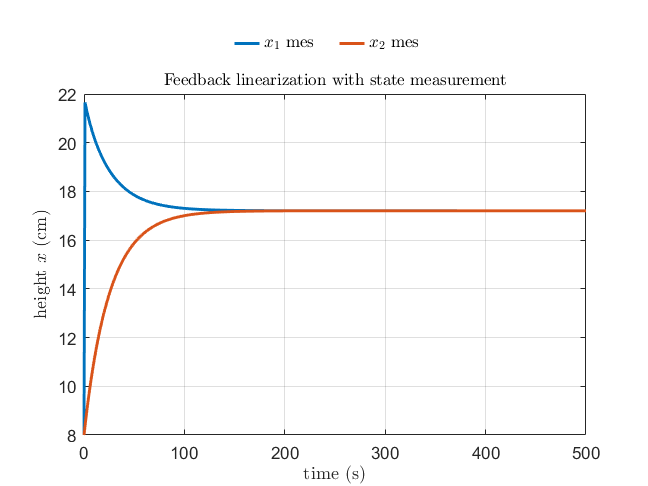

load("Results\sim_result_case_1_model");

figure();
plot(sim_result_case_1_model);
xlim([0 sim_time]);
hold on;
auto_plot('Feedback linearization with state measurement',...
        '$x_1$ mes|$x_2$ mes','time (s)|height $x$ (cm)');

saveas(gcf,'Plots/case_1_model.m');

## Case 2: you are not allowed to make use of the measurement in h1, but the measurement from h2 should be used.

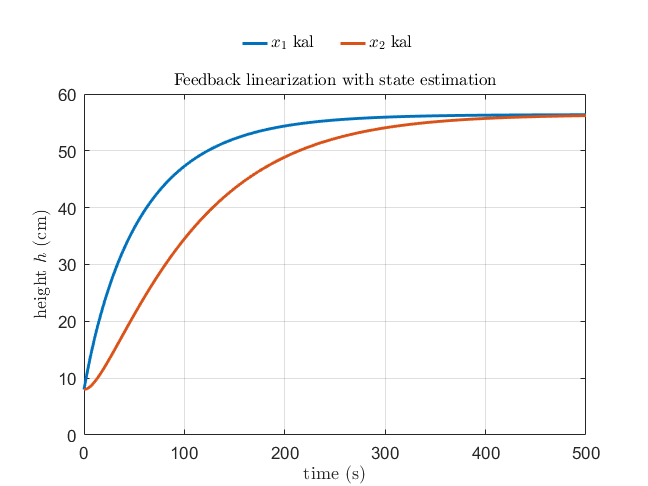

% Stuff has been copied from the lab_work_A experience
sim_u = u0_8cm;
sim("feedback_linearization_kalman_filter_sim1",sim_time);

load("Results\sim_result_case_2_model");

figure();
plot(sim_result_case_2_model);
hold on;
auto_plot('Feedback linearization with state estimation',...
        '$x_1$ kal|$x_2$ kal','time (s)|height $h$ (cm)');

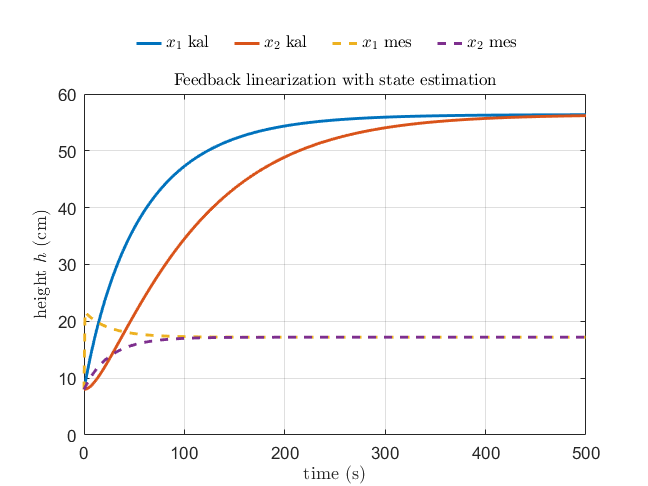

saveas(gcf,'Plots/case_2_feedback_linearization.m');

% Comparison
figure();
plot(sim_result_case_2_model);
hold on;
plot(sim_result_case_1_model,'--');
xlim([0 sim_time]);
auto_plot('Feedback linearization with state estimation',...
        '$x_1$ kal|$x_2$ kal|$x_1$ mes|$x_2$ mes','time (s)|height $h$ (cm)');

saveas(gcf,'Plots/case_1_2_comparison_model.m');